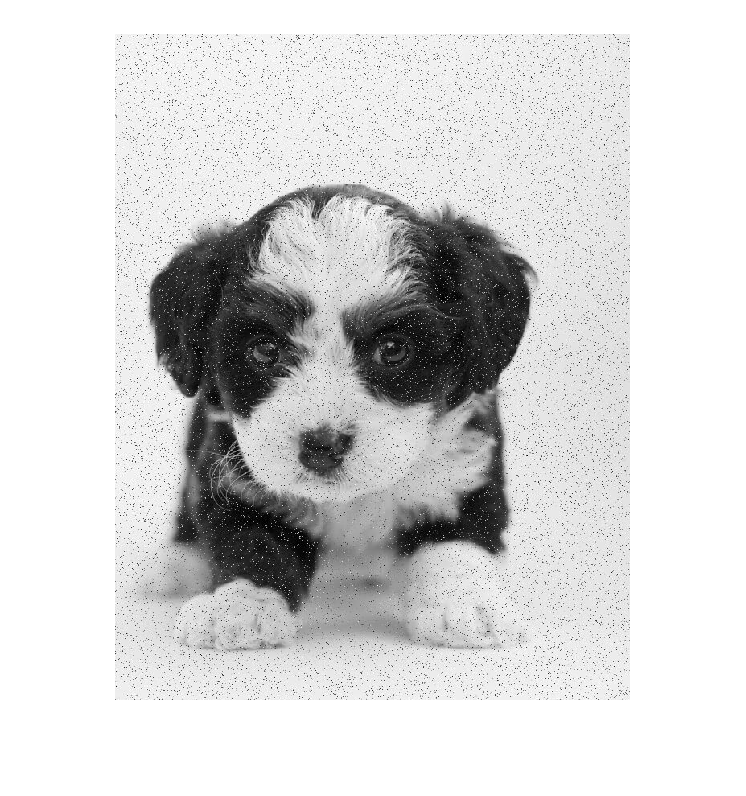

%reading image
image = imread('dog.jpg');
imshow(image)

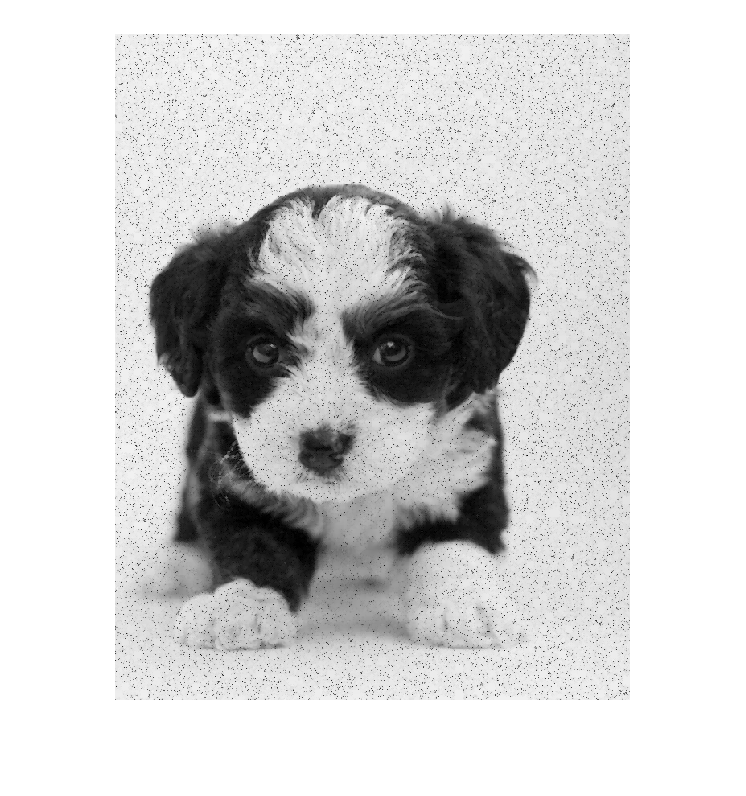


%convert the image into greyscale image if rgb
imageGrey = rgb2gray(image);
%define structural elements
structuringElement = strel('disk', 1);
%creates a disk shaped structural element with a radius of 1

%applying method of morphilogical filtering
%erosion
imageOpened = imopen(imageGrey, structuringElement);
imshow(imageOpened);

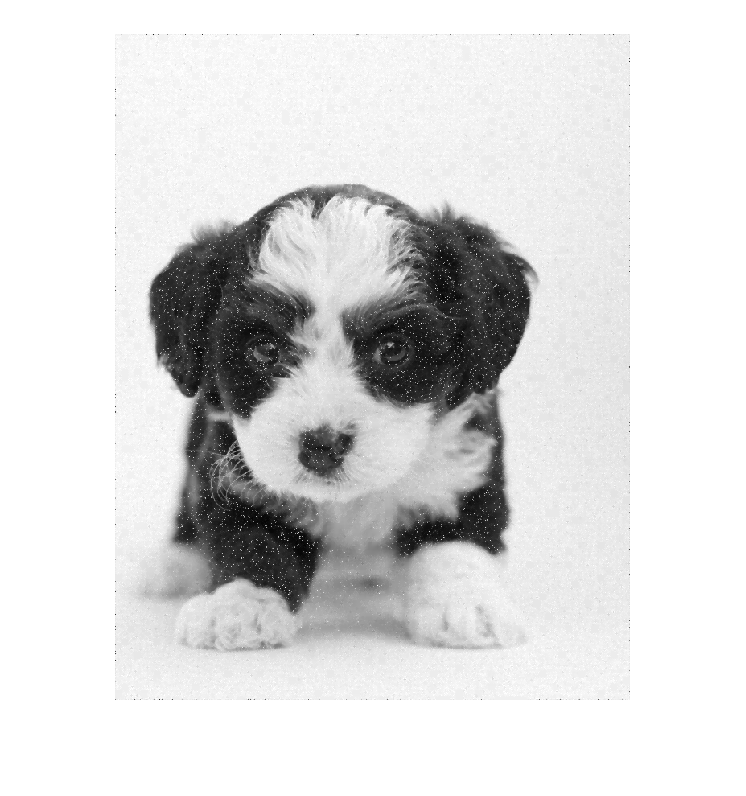


%dilation
imageClosed = imclose(imageGrey, structuringElement);
imshow(imageClosed)